data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Features_v1.csv')

data = 842×14 table
         State                  County            GoodDays    ModerateDays    UnhealthyForSensitiveGroupsDays    UnhealthyDays    VeryUnhealthyDays    HazardousDays    MaxAQI    x90thPercentileAQI    MedianAQI    COVIDDeaths_NormalizedByPopulation_    COVIDCases_NormalizedByPopulation_    COVIDCasesRates
    ________________    ______________________    ________    ____________    _______________________________    _____________    _________________    _____________    ______    __________________    _________    ____________________________


p90 = data.x90thPercentileAQI;
medAQI = data.MedianAQI;

cases = data.COVIDCases_NormalizedByPopulation_;
casesR = data.COVIDCasesRates;
deaths = data.COVIDDeaths_NormalizedByPopulation_;

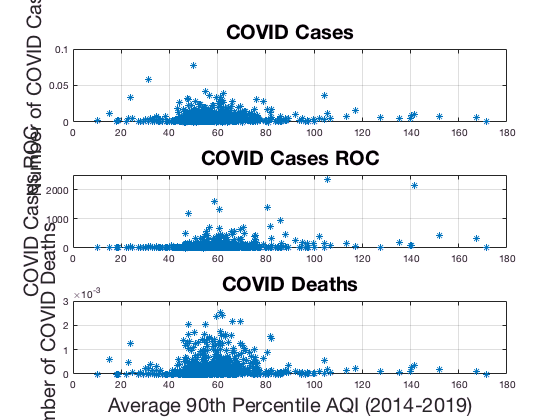

% 90th percentile plots 
figure(1) 
subplot(3,1,1) 
plot(p90,cases,'*')
grid on;
title('COVID Cases', 'FontSize', 20)
ylabel('Number of COVID Cases', 'FontSize', 20)

subplot(3,1,2) 
plot(p90,casesR,'*')
grid on;
ylim([0,2500])
title('COVID Cases ROC', 'FontSize', 20)
ylabel('COVID Cases ROC', 'FontSize', 20)

subplot(3,1,3) 
plot(p90,deaths,'*')
grid on;
title('COVID Deaths', 'FontSize', 20)
ylabel('Number of COVID Deaths', 'FontSize', 20)
xlabel('Average 90th Percentile AQI (2014-2019)', 'FontSize', 20)

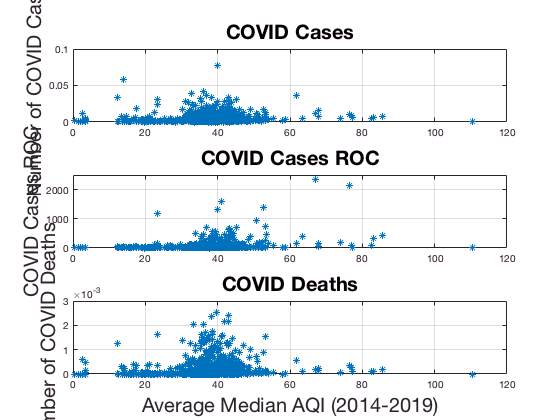

% Median plots 
figure(2) 
subplot(3,1,1) 
plot(medAQI,cases,'*')
xlim([0,90])
grid on;
title('COVID Cases', 'FontSize', 20)
ylabel('Number of COVID Cases', 'FontSize', 20)

subplot(3,1,2) 
plot(medAQI,casesR,'*')
xlim([0,90])
grid on;
ylim([0,2500])
title('COVID Cases ROC', 'FontSize', 20)
ylabel('COVID Cases ROC', 'FontSize', 20)

subplot(3,1,3) 
plot(medAQI,deaths,'*')
xlim([0,90])
grid on;
title('COVID Deaths', 'FontSize', 20)
ylabel('Number of COVID Deaths', 'FontSize', 20)
xlabel('Average Median AQI (2014-2019)', 'FontSize', 20)